## **SynDiag: Synthetic Diagnostics Simulation Module in TokaLab**

TokaLab includes a dedicated module, **SynDiag**, for simulating diagnostics and their measurements. This Live Script introduces and explains SynDiag in detail.

A **synthetic diagnostic** simulates a diagnostic system at varying levels of complexity. For example, consider simulating an air temperature measurement using a mercury thermometer. The temperature field is known at every point in the simulated environment (e.g., a room). The diagnostic can be modeled with different degrees of fidelity: you might sample the temperature near the thermometer’s location, or simulate the fluid expansion in the thermometer bulb based on heat exchange, deriving the temperature difference from the reference state. This flexibility allows users to balance computational demands with the desired level of detail.

Currently, SynDiag supports six diagnostic types:

- Pick-up coils

- Flux loops

- Saddle loops

- Thomson Scattering

- Interferometer-polarimeter

- Bolometric diagnostics

Each of these will be briefly explained in the following section.

### 1. How Diagnostics' Simulations are organised

The simulation process for each diagnostic follows a standardized structure, consisting of three primary functions:

- **Initialization**: A routine that prepares the diagnostic for the subsequent steps.

- **Upload**: This function loads a specific configuration for the diagnostic (e.g., position, laser settings for laser-based diagnostics). SynDiag includes predefined configurations for JET, DTT, and TokaLab, but users can add custom configurations by modifying the "configuration" condition in the `Upload` function of each diagnostic’s class.

- **Measurement**: Using reference fields from the equilibrium, this function simulates measurements—either by interpolating the reference field at the diagnostic’s location or by processing the fields to produce line-integrated data. Noise can also be added to the simulated measurements to better replicate real-world conditions. The specifics of this process are unique to each diagnostic and will be explored further in their respective sections.

**Script Organization**

The Live Script is structured as follows:

- The first section recaps the equilibrium simulation performed by **SimPla**.

- The next section introduces all the diagnostics, explaining their operating principles and the synthetic measurement process.

- Each diagnostic subsection concludes with examples demonstrating how parameter modifications affect the simulated results.

**Preparing for Simulation**

To simulate diagnostics and their measurements, begin by clearing the workspace, loading a machine, and solving the equilibrium. For more details, refer to **SimPla Live Script**.

Like SimPla, SynDiag adheres to principles of modularity and integrability: once a machine is selected and diagnostic configurations are set, SynDiag operates as a fully modular system.

clear; clc;
clf
close all

machine = "TokaLab";

% initialise the class tokamak
tok = tokamak();

% upload the geometry information of your tokamak
tok = tok.machine_upload(machine);

TokaLab


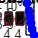

tok = tok.scenario_upload(1);
tok = tok.kinetic_upload();

% initialise the class geometry
geo = geometry;
geo = geo.import_geometry(tok);
geo = geo.build_geometry();
geo = geo.inside_wall();

% initialise the equlibrium class
equi = equilibrium;
equi = equi.import_configuration(geo,tok.config);
equi = equi.import_classes();
equi.separatrix = equi.separatrix.build_separatrix(equi.config.separatrix,equi.geo);

new_points_R = [];
new_points_Z = [];

equi = equi.solve_equilibrium_dimless();

equi = equi.equi_pp2();

equi  = equi.compute_profiles();

### 2. SynDiag: from diagnostics to synthetic ones

In this Section a brief explanation of each diagnostic and a presentation of the respective simulation code are provided. 

### 2.1 Pick-Up Coils

Pick-Up Coils are magnetic induction sensors measuring the local magnetic field induced along the coil axis unitary vecor (n) representing the coil's direction respect to the machine's frame of reference ([Donné at al, 2007](https://doi.org/10.1088/0029-5515/47/6/S07), [Hutchinson, 2002](https://doi.org/10.1017/CBO978051161363), [Wesson, 2014](https://scipub.euro-fusion.org/wp-content/uploads/2014/11/JETR99013.pdf)). Beeing i the i-th measurement, each measurement is modelled as reproted below (bein R_i and Z_i the coordinate of each coil's centre): 


$$B_{{\textrm{PU}}_i } =\mathit{\mathbf{B}}\left(R_i ,Z_i \right)\cdot n\left(R_i ,Z_i \right)$$


For what concerns the class Diag_PickUpCoils (located in SynDag_MATLAB/diagnostics) the function **measure **consists of the interpolation of magnetic field components $B_R ,B_{\phi } ,B_z$ in the points $\left(R_i ,Z_i \right)$, coordinates of each coil's centre. Then, the scalar product with the unitary vector n (defined as a parameter in the Upload function) is evaluated. 

classdef Diag_PickUpCoils

    properties

        R % Horixontal coordinate
        Z % Vertical coordinate

        n % Coil normal versor

        B % Measured Magnetic Field

        sigma_B % Associated Uncertainty to Measured Magnetic Field

        unit % Unit Measure

        config % contains the various information such as noise, etc.

        ideal % contains the measurements without the noise

    end

    methods

        function obj = measure(obj,equi)

            R_equi = equi.geo.grid.Rg;
            Z_equi = equi.geo.grid.Zg;

            Br_equi = equi.Br;
            Bt_equi = equi.Bt;
            Bz_equi = equi.Bz;

            Br = interp2(R_equi,Z_equi,Br_equi,obj.R,obj.Z);
            Bt = interp2(R_equi,Z_equi,Bt_equi,obj.R,obj.Z);
            Bz = interp2(R_equi,Z_equi,Bz_equi,obj.R,obj.Z);

To make the simulated measurement resemble the real one, noise is added. More specifically, it is possible to perturbate the ideal measurements obtained with both an absolute noise and a proportional one:

            obj.ideal.B = sum([Br; Bt; Bz].*obj.n);

            % noise absolute
            noise_abs = normrnd(0,obj.config.noise_random_absolute_intensity,size(obj.ideal.B));

            % noise proportional
            noise_prop = normrnd(0,abs(obj.ideal.B).*obj.config.noise_random_proportional_intensity);

            % real measurement
            obj.B = obj.ideal.B + noise_abs + noise_prop;

 The resulting measurement will be the ideal one (coming from the interpolation) and the added noise (which is an input parameter that can be selected in the Upload function). It is also possible to determine the measurement's associated uncertainty defined as: 

            %associated uncertainty
            obj.sigma_B = sqrt(obj.config.noise_random_absolute_intensity.^2 +...
                (abs(obj.ideal.B).*obj.config.noise_random_proportional_intensity).^2);

            obj.unit = "T"; % tesla

        end

For what concerns the function Upload, it is organised as follows: at first some if conditions on user's input are introduced to avoid error on missing entries: 

        function obj = Upload(obj,configuration,machine)

            % default configuration
            if nargin<2
                configuration = 1;
                machine = "TokaLab";
            elseif nargin < 3
                machine = "TokaLab";
            end

Then, different cnfigurations are defined. By adding another condition on the if condition, the user is able to introduce new configurations. At the moment three of them are defined: the TokaLab standard (configuration == 1), the JET-like (configuration == 2) and the DTT-like (configuration == 3). To add a new one, the user can create a .mat file, as the one present in the subfolders in the diagnostics' folder or can define the necessary quantities (n, R, Z) directly inside the Upload function. 

            %%%%%%%%%%%% TokaLab Configuration %%%%%%%%%%%%%%%%%%%%%%%%%%%%

            if machine == "TokaLab"

                if configuration == 1

                    obj.config.configuration = 1;

                    load("PickUpData_TokaLab_config_1.mat")

                    obj.R = R;
                    obj.Z = Z;
                    obj.n = n;

                    obj.config.noise_random_absolute_intensity = 0;
                    obj.config.noise_random_proportional_intensity = 0;

                end

            end

            %%%%%%%%%%%% JET-like Configuration %%%%%%%%%%%%%%%%%%%%%%%%%%%%

            if machine == "JET-like"

                if configuration == 1

                    obj.config.configuration = 1;

                    load("PickUpData_JETlike_config_1.mat")

                    obj.R = R;
                    obj.Z = Z;
                    obj.n = n;

                    obj.config.noise_random_absolute_intensity = 0;
                    obj.config.noise_random_proportional_intensity = 0;

                end

            end

            %%%%%%%%%%%% DTT-like Configuration %%%%%%%%%%%%%%%%%%%%%%%%%%%%

            if machine == "DTT-like"

                if configuration == 1

                    obj.config.configuration = 1;

                    load("PickUpData_DTTlike_config_1.mat")

                    obj.R = R;
                    obj.Z = Z;
                    obj.n = n;

                    obj.config.noise_random_absolute_intensity = 0;
                    obj.config.noise_random_proportional_intensity = 0;

                end

            end

        end

The last function contained in this class is a simple plot function to show the location of the pick-up coils and to plot measurements produced by the simulated diagnostic. 

        %% Plotting Functions

        function plot_geo(obj)

            plot(obj.R,obj.Z,'.','MarkerSize',16)
            grid on
            grid minor
            xlabel("R")
            ylabel("Z")

        end

        function plot_meas(obj)

            plot(obj.B,'.','MarkerSize',16)
            grid on
            grid minor
            xlabel("#")
            ylabel("B [T]")

        end

        function plot_StandAlone(obj)

            hold off
            plot(obj.ideal.B,'.b','MarkerSize',16)
            hold on
            plot(obj.B,'or','LineWidth',1.2)
            grid on
            grid minor
            xlabel("#")
            ylabel("B [T]")

        end

    end

end

Illegal use of reserved keyword "classdef".